% MATLAB Radar sensing experiment

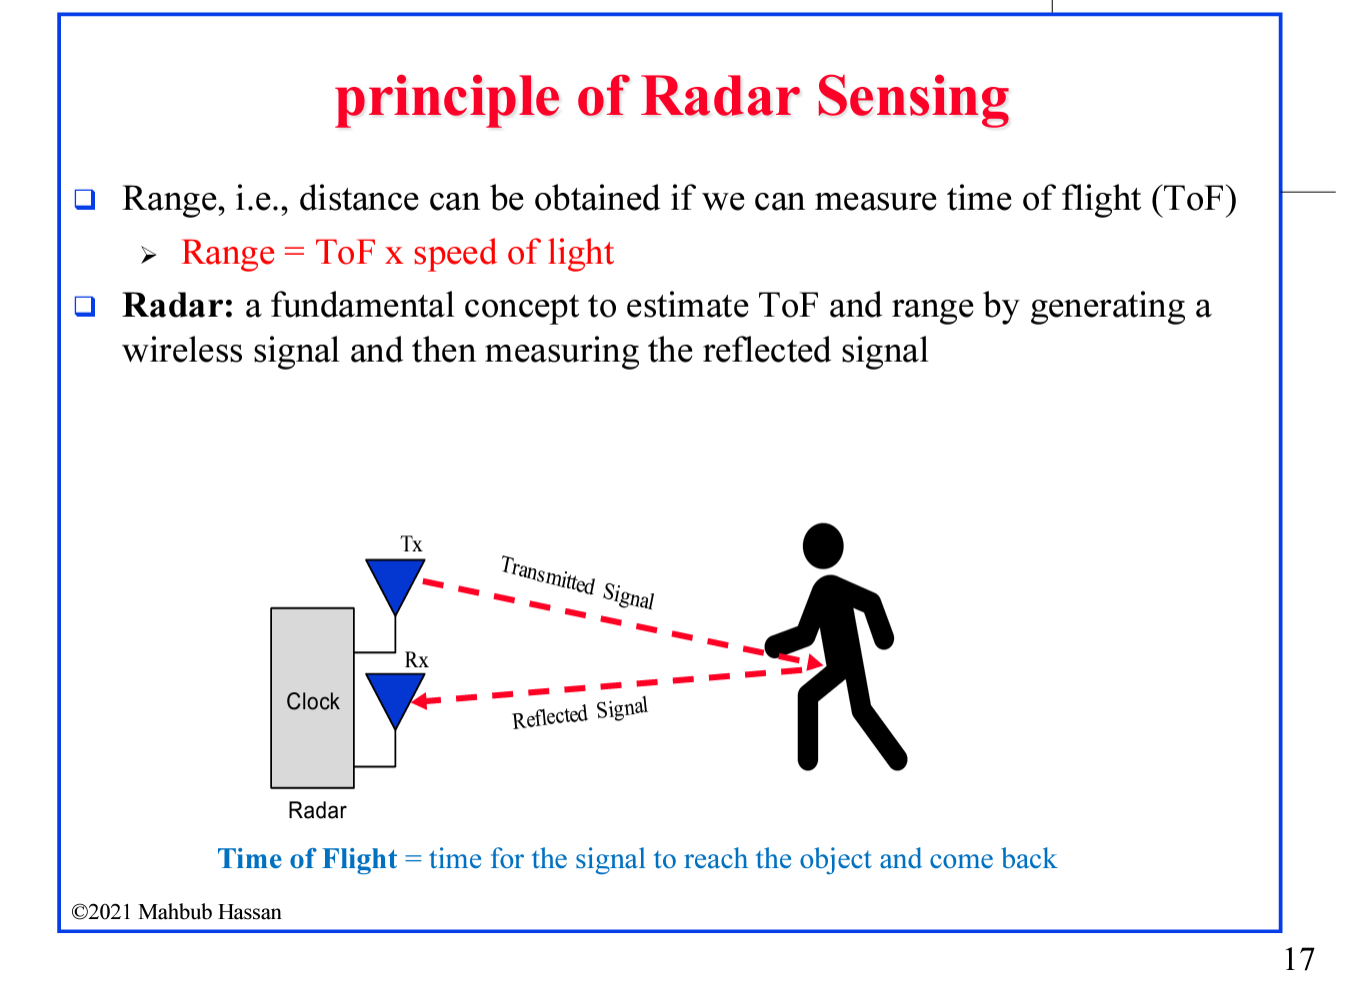

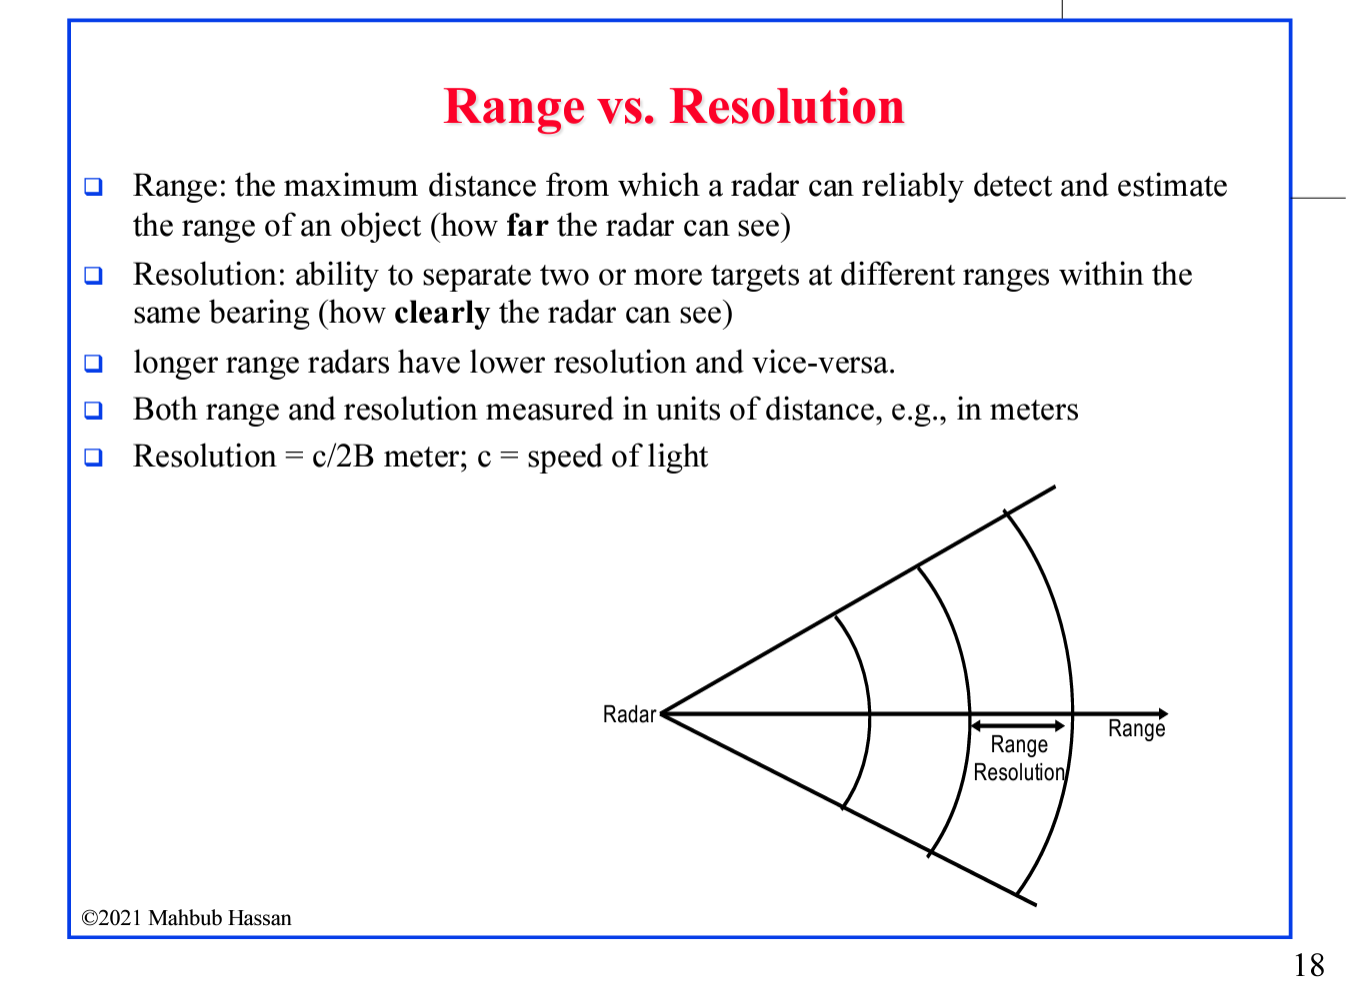

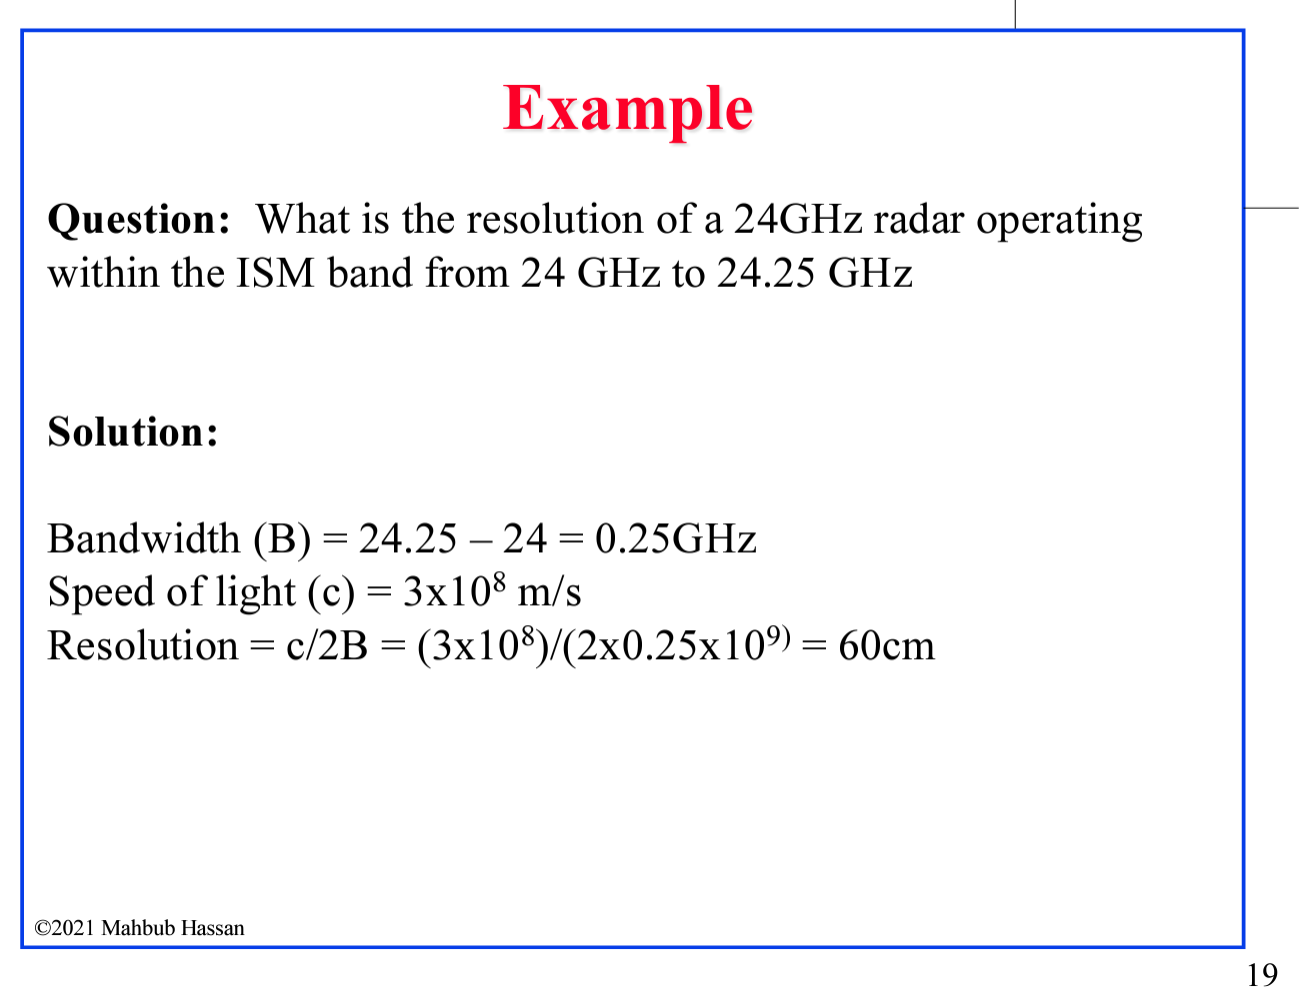

**TOPIC: **

FMCW radar distance sensing in MATLAB

## Simulate Senario

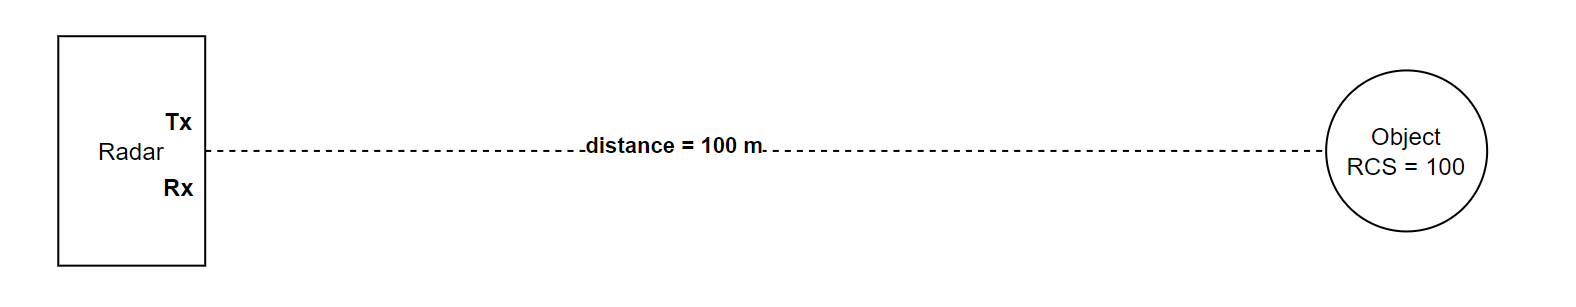

### **Senario description**

 There is an object 100 meters away from the FMCW radar. The RCS is set to 100 for the object. Both the radar and object are stationary (not moving).

 Now let's simulate how the FMCW radar can detect the range of the object. The radar parameters are as follows:

### ** Parameters:**

-         Radar Freq                                 = 24 GHz

-         Bandwidth                                  = 150 MHz

-         speed of light                             = 3e8 meters/sec

-         sweep time                                = 5.5 μs

-         sweep slope = bandwidth / sweep time = 2.7273e13 Hz/sec

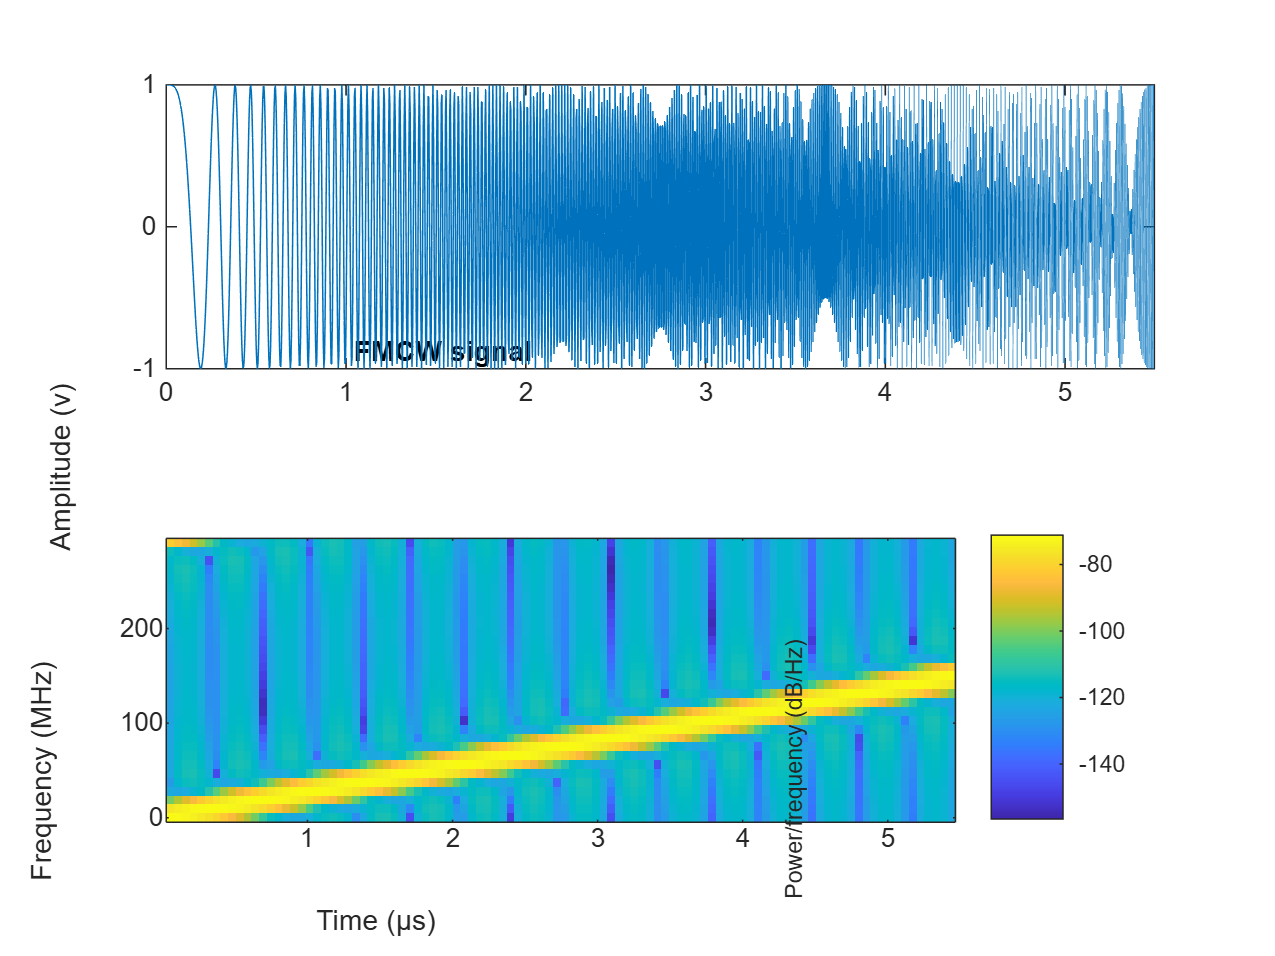

% env setup
fc = 24e9;               % frequency
c = 3e8;                 % speed of light
lambda = c/fc;          
range_max = 150;         % unambiguous maximum range for radar
tm = 5.5*range2time(range_max,c);  % sweep time = 5.5 microsecond (5.5000e-06 s)
                         % for an FMCW radar system, the sweep time should be at least five to six times the round trip time

range_res = 1;           % range resolution  (normally 60cm for 24GHz, 15cm for 77GHz)
bw = 150e6;              % bandwidth 150MHz
sweep_slope = bw/tm;     % sweep slope 2.7273e+13
v_max = 230*1000/3600; % max detected speed is 230km/h
fs = 2 * bw; % sample rate: use the max value between 2*maximum beat frequency or the bandwidth



% create FMCW chirp and plot it
waveform = phased.FMCWWaveform('SweepTime',tm,'SweepBandwidth',bw, ...
    'SampleRate',fs);

sig = waveform();
subplot(211); plot(0:1/fs:tm-1/fs,real(sig));
xlabel('Time (s)'); ylabel('Amplitude (v)');
title('FMCW signal'); axis tight;
subplot(212); spectrogram(sig,32,16,32,fs,'yaxis');
title('FMCW signal spectrogram');


% specanalyzer for later usage
specanalyzer = spectrumAnalyzer('SampleRate',fs, ...
    'Method','welch','AveragingMethod','running', ...
    'PlotAsTwoSidedSpectrum',true, 'FrequencyResolutionMethod','rbw', ...
    'Title','Spectrum for received and dechirped signal', ...
    'ShowLegend',true);

% set the object to be detected

obj_dist = 100; % distance in meters
obj_speed = 0; % 0 km/h
obj_rcs = 100; % this equation comes from Kärnfelt, Camilla, Alain Péden, Ali Bazzi, Ghayath El Haj Shhadé, Mohamad Abbas, and Thierry Chonavel. ‘77 GHz ACC Radar Simulation Platform’. In 2009 9th International Conference on Intelligent Transport Systems Telecommunications, (ITST), 209–14, 2009. https://doi.org/10.1109/ITST.2009.5399354.

objtarget = phased.RadarTarget('MeanRCS',obj_rcs,'PropagationSpeed',c,...
    'OperatingFrequency',fc);
objmotion = phased.Platform('InitialPosition',[obj_dist;0;0],...
    'Velocity',[obj_speed;0;0]);


% config the radar
channel = phased.FreeSpace('PropagationSpeed',c,...
    'OperatingFrequency',fc,'SampleRate',fs,'TwoWayPropagation',true);

% radar param from  Kärnfelt, Camilla, Alain Péden, Ali Bazzi, Ghayath El Haj Shhadé, Mohamad Abbas, and Thierry Chonavel. ‘77 GHz ACC Radar Simulation Platform’. In 2009 9th International Conference on Intelligent Transport Systems Telecommunications, (ITST), 209–14, 2009. https://doi.org/10.1109/ITST.2009.5399354.
ant_aperture = 6.06e-4;                         % in square meter
ant_gain = aperture2gain(ant_aperture,lambda);  % 27 dBi
tx_ppower = db2pow(5)*1e-3;                     % in watts
tx_gain = ant_gain;                           % in dBi  
rx_gain = ant_gain;                          
rx_nf = 4.5;                                    % in dB

transmitter = phased.Transmitter('PeakPower',tx_ppower,'Gain',tx_gain);

receiver = phased.ReceiverPreamp('Gain',rx_gain,'NoiseFigure',rx_nf,...
    'SampleRate',fs);

% radar_speed = 0  not moving
radar_speed = 0;
radarmotion = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[radar_speed;0;0]);

### Calculation on the range:

The relationship between the slope, τ and ΔF:

**                               (slope * τ)^2 = ΔF^2 + τ^2**

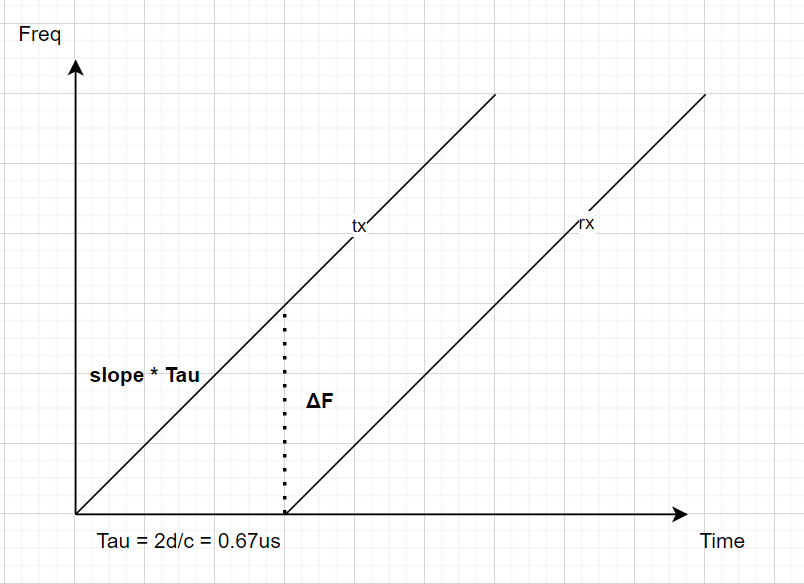

 To measure the range (and Doppler), an FMCW radar typically performs the following operations:

- The waveform generator generates the FMCW signal.

- The transmitter and the antenna amplify the signal and radiate the signal into space.

- The signal propagates to the target, gets reflected by the target, and travels back to the radar.

- The receiving antenna collects the signal.

- The received signal is dechirped and saved in a buffer.

- Once a certain number of sweeps fill the buffer, the Fourier transform is performed in both range and Doppler to extract the beat frequency as well as the Doppler shift. can then estimate the range and speed of the target using these results. Range and Doppler can also be shown as an image and give an intuitive indication of where the target is in the range and speed domain.

**Here are the simulation on matlab:**


rng(2012); % random seed
Nsweep = 1; % sweep 1 times

% create databox for dechirp signals
xr = complex(zeros(waveform.SampleRate*waveform.SweepTime,Nsweep));

for m = 1:Nsweep
    % Update radar and target positions
    [radar_pos,radar_vel] = radarmotion(waveform.SweepTime);
    [tgt_pos,tgt_vel] = objmotion(waveform.SweepTime);


    % Transmit FMCW waveform
    sig = waveform();
    txsig = transmitter(sig);


    % Propagate the signal and reflect off the target 
    % https://ww2.mathworks.cn/help/phased/ref/phased.freespace-system-object.html
    txsig = channel(txsig,radar_pos,tgt_pos,radar_vel,tgt_vel); 
    txsig = objtarget(txsig);


    % Dechirp the received radar return
    rcvdsig = receiver(txsig); 
    dechirpsig = dechirp(rcvdsig,sig); % dechirp(received signal,reference signal) mixes the incoming signal, x, with the reference signal, xref. 
    xr(:,m) = dechirpsig; % https://ww2.mathworks.cn/help/phased/ug/fmcw-range-estimation.html


end

### **Calculation on distance estimation:**

    We already know the object distance = 100 meters from the FMCW radar, 

    so the RTT  τ = 2d / c = ???

    **ΔF **= sqrt ((Slope*τ)^2 - τ^2) = ??? 

#### Verify the calculation of  beat frequency  (range to beat):

% calculate the delta F (beat frequency)
slope = sweep_slope;
tau = 2*obj_dist/c;
delta_F = sqrt((slope*tau)^2 - tau^2);
fprintf('When the slope is %.2d, tau is %.2d sec, delta F will be %.2f Hz',slope,tau,delta_F);

When the slope is 2.73e+13, tau is 6.67e-07 sec, delta F will be 18181818.18 Hz


% verify the delta F via matlab built-in function range2beat
fprintf('(matlab built-in function range2beat)  delta F will be %.2f Hz', range2beat(obj_dist, slope, c));

(matlab built-in function range2beat)  delta F will be 18181818.18 Hz

**  Now lets verify the simulated result,  ΔF in the specanalyzer:**

% specanalyzer([dechirpsig]);  % find the peak with the specanalyzer

max_allowed_freq = range2beat(range_max,slope,c) % max_range 150meters -> 27.273 MHz

max_allowed_freq = 2.7273e+07

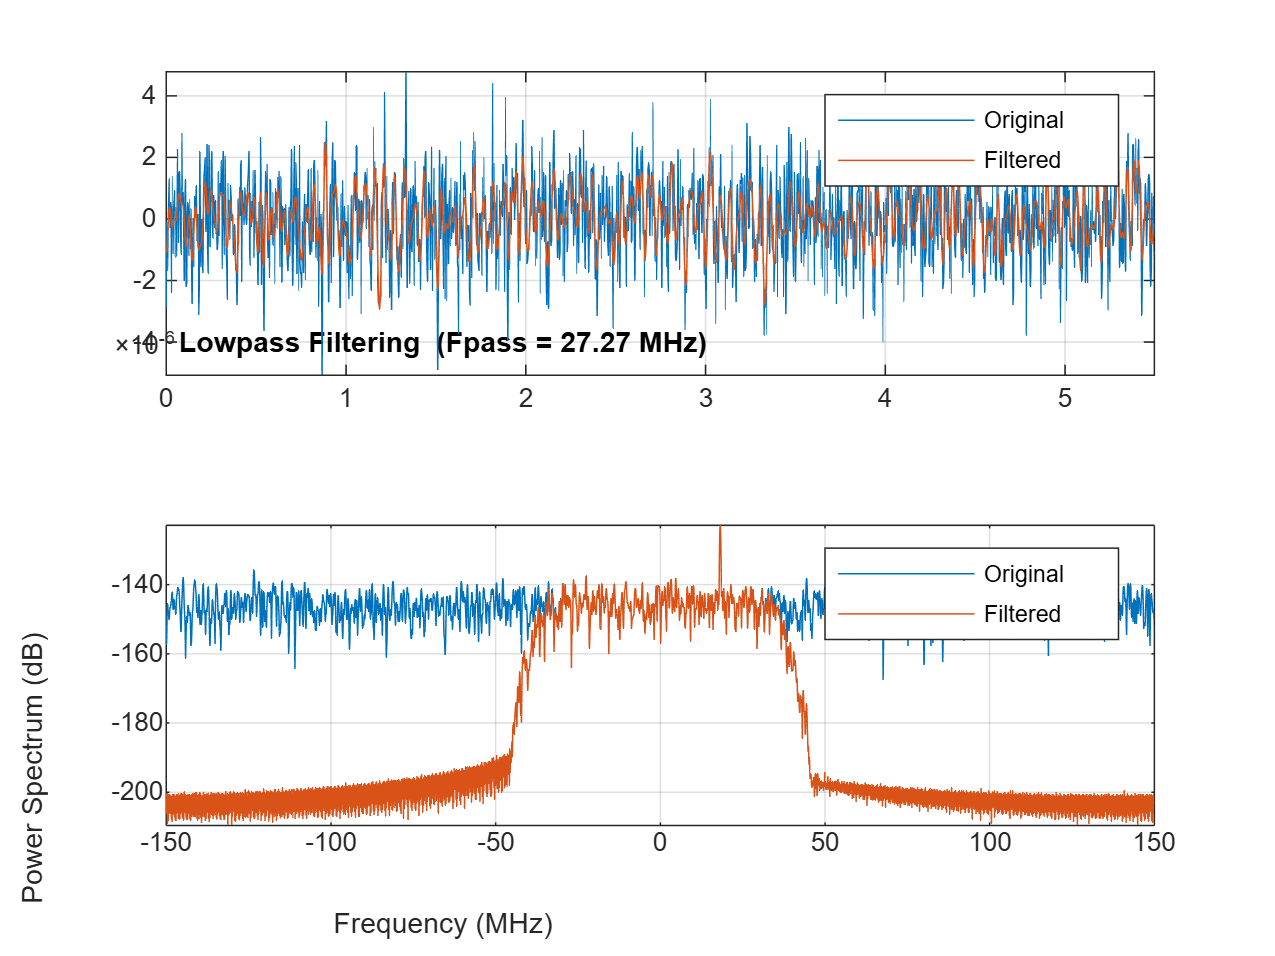

filtered_dechirpsig = lowpass(dechirpsig, max_allowed_freq ,fs);
lowpass(dechirpsig, max_allowed_freq ,fs);

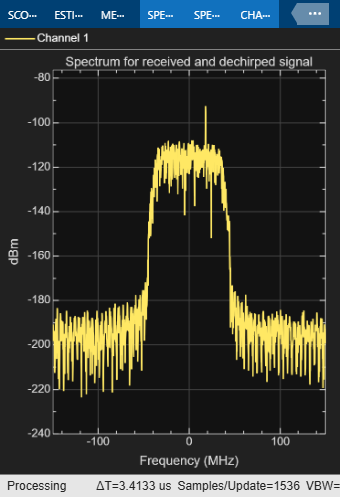

specanalyzer([filtered_dechirpsig]);  % find the peak with the specanalyzer

#### Now lets verify the calculation of range (ΔF to range):

% verify the range with delta
distance = c * delta_F / sqrt(4*slope^2-4); % equation to distance
fprintf('When the slope is %.2f, delta F is %.2f Hz, \n object distance will be %.2f meters',slope,delta_F, distance);

When the slope is 27272727272727.27, delta F is 18181818.18 Hz, 
 object distance will be 100.00 meters

% or can use the built-in function 
fprintf('(matlab built-in function beat2range)  distance will be %.2f meters',beat2range(delta_F, slope, c));

(matlab built-in function beat2range)  distance will be 100.00 meters

Let's try FFT now

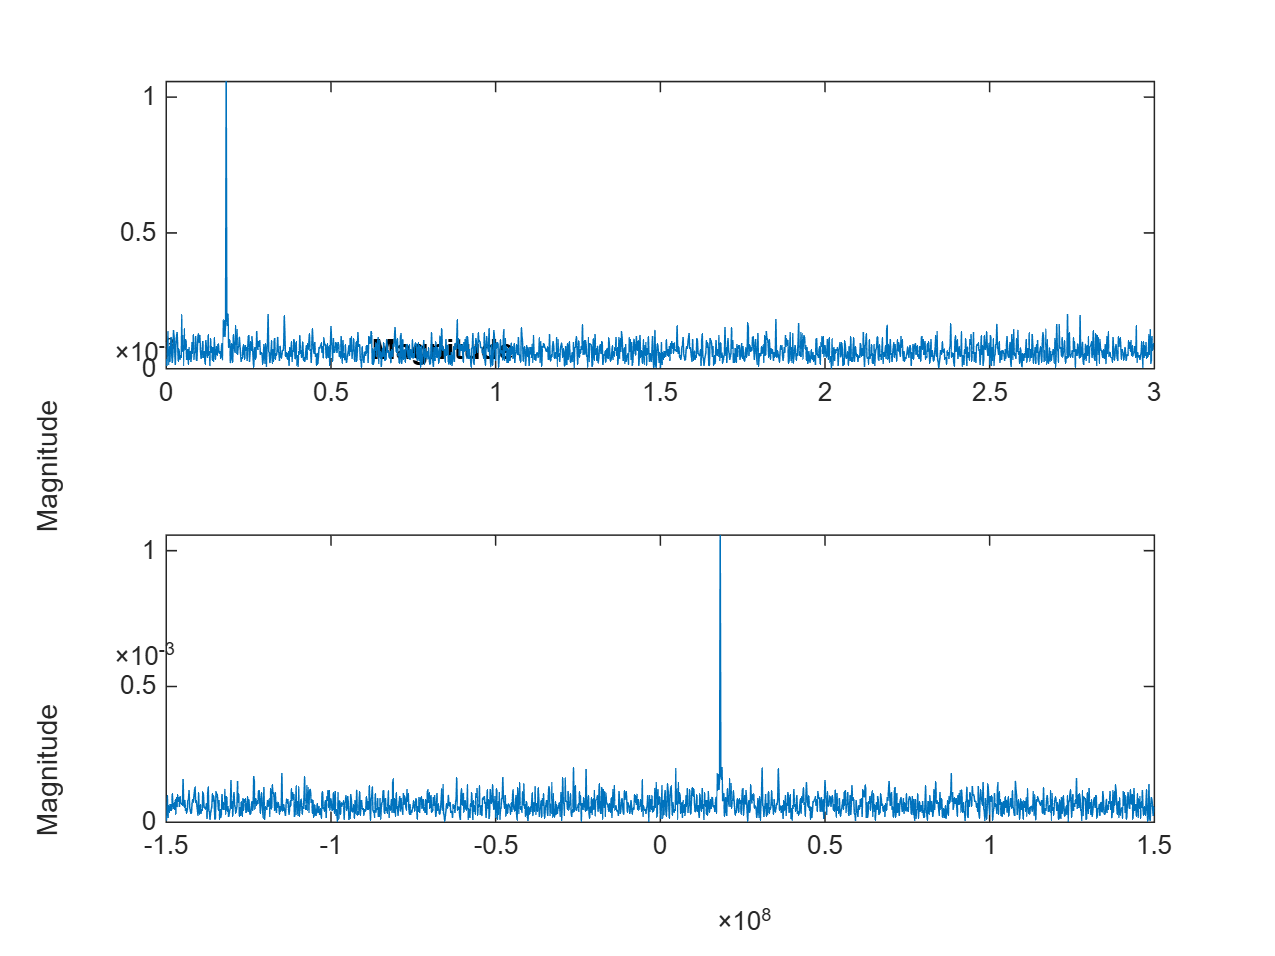


% Or use the FFT methods https://ww2.mathworks.cn/help/matlab/math/fourier-transforms.html
figure; 
fft_y = fft(dechirpsig);
fft_x = (0:length(fft_y)-1)*fs/length(fft_y);
subplot(2,1,1), plot(fft_x, abs(fft_y));
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')

%The discrete Fourier transform of a time-domain signal has a periodic nature, 
% where the first half of its spectrum is in the positive frequencies and the second half is in the negative frequencies. 
% To better visualize this periodicity, you can use the fftshift function, which performs a zero-centered, circular shift on the transform.

n = length(fft_x);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(fft_y);
subplot(2,1,2), plot(fshift,abs(yshift));
ylabel('Magnitude');

% Or use rootmusic algorithm to find the beat frequency and do the range estimation
% firstly, estimate the beat frequency using the coherently integrated sweeps 
fb_rng = rootmusic(pulsint(xr,'coherent'),1,fs);
% and then converted to the range.
rng_est = beat2range(fb_rng,sweep_slope,c);
% peak_loc = val2ind(rng_est,c/(fs_d*2));
fprintf('range: %3.2f meters\n',rng_est);

range: 101.50 meters
